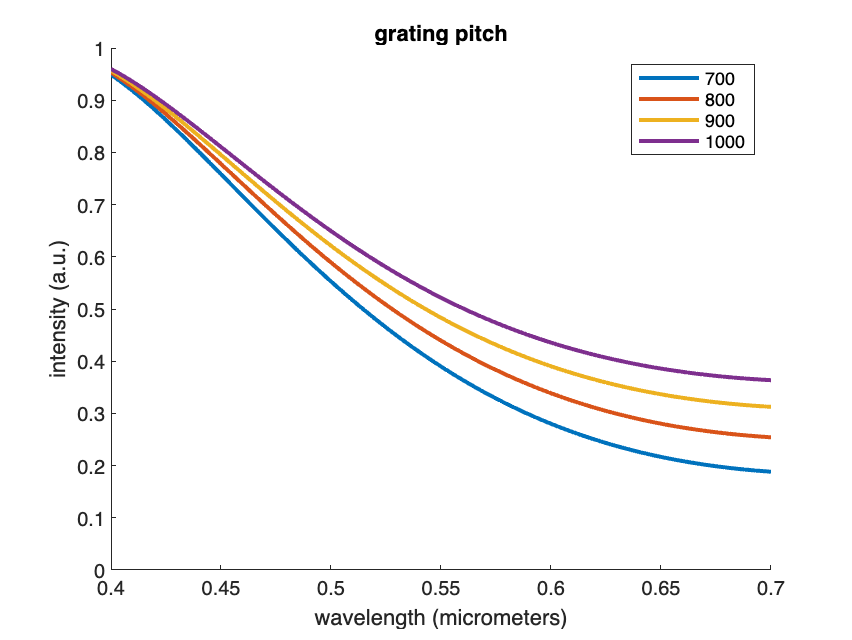

% grating pitch model

lambda=0.400:0.001:0.700;

A=1.52266;
B=0.000733;
C=-0.0000482;
n_lambda=A+(B*(lambda.^-2))+(C*(lambda.^-4));
gp=[0.7;0.8;0.9;1];
w1=0.1;
w2=0.2;
D1=w1./gp;
D2=w2./gp;

navg1=(((gp-w1)./gp)*1)+(n_lambda.*(w1./gp));
navg2=(((gp-w2)./gp)*1)+(n_lambda.*(w2./gp));

d1=200/1000; %thickness of each layer
d2=800/1000;

dphi1=2*pi./lambda.*d1.*(n_lambda-1);
dphi2=2*pi./lambda.*d2.*(n_lambda-1);

m=0;
eta1_0gp=1-(2.*D1)+(2.*D1.^2)+(2.*D1.*(1-D1).*cos(dphi1));
eta2_0gp=1-(2.*D2)+(2.*D2.^2)+(2.*D2.*(1-D2).*cos(dphi2));

m=1;
eta1_1gp=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_1gp=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

eta_totalgp=eta2_0gp; 

figure
hold on
%for i=1:length(gp)
   % plot(lambda,eta_totalgp(i,:),'LineWidth',2)
%end
plot(lambda,eta_totalgp(1,:),'LineWidth',2)
plot(lambda,eta_totalgp(2,:),'LineWidth',2)
plot(lambda,eta_totalgp(3,:),'LineWidth',2)
plot(lambda,eta_totalgp(4,:),'LineWidth',2)
hold off
ylim([0 1])
xlabel 'wavelength (micrometers)'
ylabel 'intensity (a.u.)'
title 'grating pitch'
legend('700','800','900','1000')

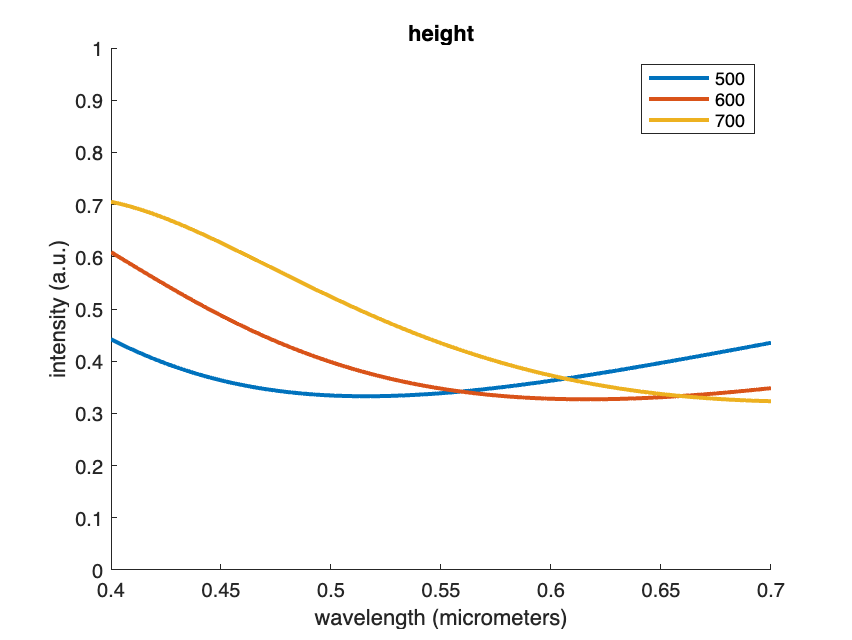

% height model

lambda=0.400:0.001:0.700;

A=1.52266;
B=0.000733;
C=-0.0000482;
n_lambda=A+(B*(lambda.^-2))+(C*(lambda.^-4));
gp=1;
w1=0.1;
w2=0.2;
D1=w1./gp;
D2=w2./gp;

%d1=[186;283;175;321;207;178]/1000; %thickness of each layer
%d2=[691;839;694;907;716;662]/1000;
d1=[150;200;250]/1000;
%d2=[400;500;600;700]/1000;
d2=[500;600;700]/1000;

dphi1=2*pi./lambda.*d1.*(n_lambda-1);
dphi2=2*pi./lambda.*d2.*(n_lambda-1);

m=0;
eta1_0h=1-(2.*D1)+(2.*D1.^2)+(2.*D1.*(1-D1).*cos(dphi1));
eta2_0h=1-(2.*D2)+(2.*D2.^2)+(2.*D2.*(1-D2).*cos(dphi2));

m=1;
eta1_1h=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_1h=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);

eta_totalh=eta1_0h.*eta2_0h;

figure
for i=1:length(d2)
    hold on
    plot(lambda,eta_totalh(i,:),'LineWidth',2)
end
hold off
ylim([0 1])
xlabel 'wavelength (micrometers)'
ylabel 'intensity (a.u.)'
title 'height'
legend('500','600','700')

%legend('690','839','694','907','716','662')

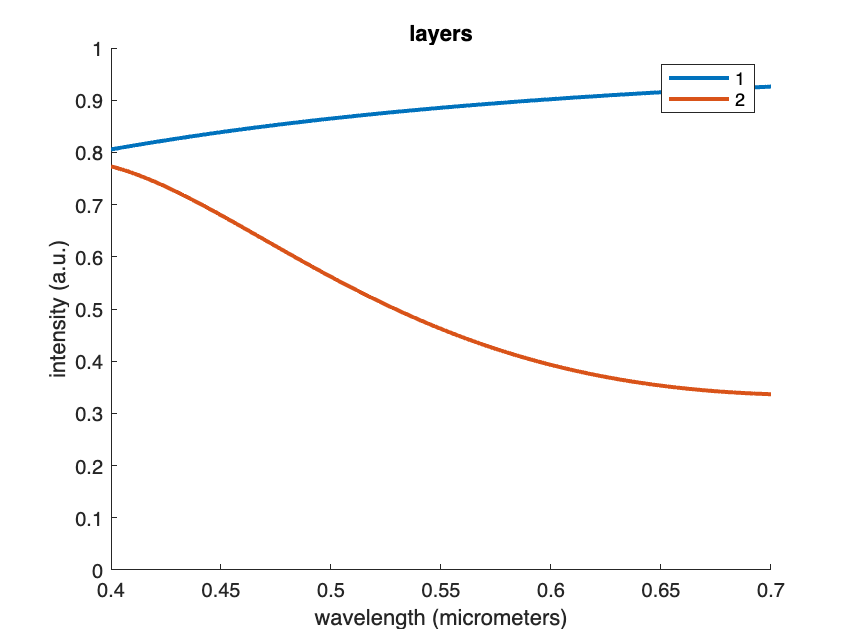

%layers model

lambda=0.400:0.001:0.700;

A=1.52266;
B=0.000733;
C=-0.0000482;
n_lambda=A+(B*(lambda.^-2))+(C*(lambda.^-4));
gp=1;
w1=0.1;
w2=0.2;
w3=0.2;
D1=w1./gp;
D2=w2./gp;
D3=w3./gp;

d1=200/1000; %thickness of each layer
d2=700/1000;
d3=700/1000;

dphi1=2*pi./lambda.*d1.*(n_lambda-1);
dphi2=2*pi./lambda.*d2.*(n_lambda-1);
dphi3=2*pi./lambda.*d3.*(n_lambda-1);

m=0;
eta1_0l=1-(2.*D1)+(2.*D1.^2)+(2.*D1.*(1-D1).*cos(dphi1));
eta2_0l=1-(2.*D2)+(2.*D2.^2)+(2.*D2.*(1-D2).*cos(dphi2));
eta3_0l=1-(2.*D3)+(2.*D3.^2)+(2.*D3.*(1-D3).*cos(dphi3));

m=1;
eta1_1l=4/pi^2/m^2.*(sin(pi.*m.*D1).^2).*(sin(dphi1./2).^2);
eta2_1l=4/pi^2/m^2.*(sin(pi.*m.*D2).^2).*(sin(dphi2./2).^2);
eta3_1l=4/pi^2/m^2.*(sin(pi.*m.*D3).^2).*(sin(dphi3./2).^2);

eta_total1=eta1_0l;
eta_total2=eta2_0l.*eta1_0l;
eta_total3=eta2_0l.*eta1_0l.*eta3_0l;

figure
hold on
plot(lambda,eta_total1,'LineWidth',2)
plot(lambda,eta_total2,'LineWidth',2)
plot(lambda,eta_total3,'LineWidth',2)
hold off
ylim([0 1])
xlabel 'wavelength (micrometers)'
ylabel 'intensity (a.u.)'
title 'layers'
legend('1','2','3')